## Introduction

MultiLayerPerceptron consists of a MATLAB class including a configurable multi-layer perceptron (or feedforward neural network) and the methods useful for its setting and its training.

The multi-layer perceptron is fully configurable by the user through the definition of lengths and activation functions of its successive layers as follows:

- Random initialization of weights and biases through a dedicated method,

- Setting of activation functions through method "set".

The training method of the neural network is based on the following algorithms:

- Gradient descent, with configurable learning rate, momentum and size of batches,

- Levenberg-Marquardt, with configurable parameters and an optional bayesian regularization.

The evolution of the training is viewable through an embedded visualization window and configurable in terms of:

- Minimum mean square error (MSE),

- Number of epochs,

- Ratio between training and validation data sets.

## Properties, public

- **LengthsOfLayers :** line vector containing the lengths of the successive layers (numbers of nodes of inputs, hidden and outputs layers).

- **Weights :** line cell containing the weights of the successive layers as matrices (size : number of nodes in previous layer x number of nodes in current layer, 0 x 0 for the first value).

- **Biases :** line cell containing the biases of the successive layers as vectors (size : number of nodes in previous layer x 1, 0 x 0 for the first value).                      

- **HiddenActFcn :** name of the activation function of hidden layers, among 'linear', 'logistic', 'ReLU' and 'tanh' (default value : 'tanh').

- **OutputActFcn : **name of the activation function of output layer, among 'linear', 'logistic', 'ReLU', 'tanh' and 'softmax' (default value : 'softmax').

- **TrainingAlgorithm :** name of the training algorithm, "Gradient descent" (or "GD") or "Levenberg-Marquardt" (or "LM") (default value: "GD").

- **SplitRatio :** split ratio between training and validation data sets, between 0 and 1 (default value: 0.7).

- **NumberOfEpochs :** maximum number of epochs during training (default value: 200).

- **MinimumMSE : **minimum mean square error to abort training (default value: 1e-3).

- **UpdateFcn : **update function, called at every epoch of training, "none" (default value), "default" (default GUI) or user defined function (input argument: trained multi-layer perceptron, output argument: training continuation boolean).

- **LearningRate : **learning rate, applicable if the training algorithm is "GD" (default value: 0.15).

- **SizeOfBatches : **size of the training batches, applicable if the training algorithm is "GD" (default value: 32).

- **Momentum : **momentum, applicable if training algorithm is "GD" and the size of batches is 1 (default value: 0.9).

- **InitialMarquardtParameter : **initial value of Levenberg-Marquardt parameter, applicable if the training algorithm is "LM" (default value: 0.01).

- **MaximumMarquardtParameter : **maximum value of Levenberg-Marquardt parameter, applicable if the training algorithm is "LM" (default value: 1e10).

- **MarquardtFactor : **value of the evolution factor of Levenberg-Marquardt parameter, applicable if the training algorithm is "LM" (default value: 10).

- **BayesianRegularization :** boolean for the activation of bayesian regularization, applicable if the training algorithm is "LM" (default value: "false").

## Properties, read only

- **Outputs : **ouputs corresponding to the inputs propagated through method "propagate".

- **CurrentEpoch : **current epoch of the training.

- **MeanSquareErrors : **mean square errors vector until the current epoch of the training.

- **ValidationMeanSquareErrors : **mean square errors vector on the validation set until the current epoch of the training.

- **TrainingStep : **training step among "start", "update" and "stop".

## **Methods**

- **MultiLayerPerceptron :** constructor of the class

- **set :** method to set public properties

- **get :** method to get public properties

- **initialize** : method to randomly initialize the weights and the biases of the layers, whose numbers are defined by property "LengthsOfLayers".

- **propagate :** method to propagate the inputs defined by the user as an input argument and available through property "Outputs".

- **train : **method to train the multi-layer perceptron, depending of the training algorithm, defined by property "TrainingAlgorithm".

## Example: **Classification of sectors with gradient descent algorithm**

- **Step #1: Definition of the sectors**

% Parameter
N = 24;

% Coordinates
V = linspace(-2,+2,N);       
[X,Y] = ndgrid(V,V);      
Coordinates = [X(:)';Y(:)'];   

% Regions
Regions = 1*ge(Y,X)+2*(gt(Y,-X)|lt(abs(X+Y),1e-2))+1;
Regions = Regions(:)';

% Figure
Figure = figure('Color','w');
axis('off');
hold('on');
Colors = {'m','g','c','y'};

% Plot
for r = 1:4
    I = find(eq(Regions,r));
    plot(Coordinates(1,I),Coordinates(2,I),'o',...
        'MarkerEdgeColor',  'k',...
        'MarkerFaceColor',  Colors{r},...
        'MarkerSize',       6);
end        
xlim([-2 +2]);
ylim([-2 +2]);
axis('equal');
drawnow();


- **Step #2: Training with gradient descent algorithm**

% Probabilities
Probabilities = zeros(4,numel(Regions));
for n = 1:numel(Regions)
    Probabilities(Regions(n),n) = 1;
end

% Multi-layer perceptron
MLP = ...
    MultiLayerPerceptron('LengthsOfLayers', [2 4 4],...
                         'HiddenActFcn',     'linear',...
                         'OutputActFcn',     'softmax');

% Options                     
Options = ...
    struct('TrainingAlgorithm', 'GD',...
           'NumberOfEpochs',    50,...
           'MinimumMSE',        1e-2,...
           'SizeOfBatches',     10,...
           'SplitRatio',        1,...
           'Momentum',          0.9);

% Training       
MLP.train(Coordinates,Probabilities,Options);


- **Step #3: Plot of the map in terms of the regions calculated by the multi-layer perceptron**

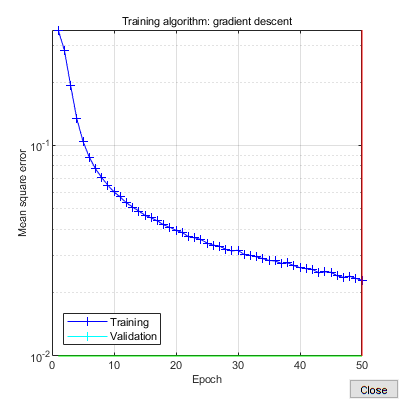

% Map colors
Colors = ...
    [1 0 0;...
     0 1 0;...
     0 0 1;...

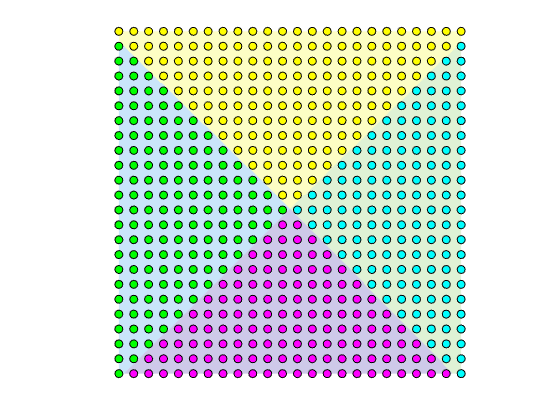

     1 1 0];


% Coordinates of the coloration points
N2 = 300;
V = linspace(-2,+2,N2);       
[X,Y] = ndgrid(V,V);      
Coordinates2 = [X(:)';Y(:)'];  

% Most probable regions
MLP.propagate(Coordinates2);
Probabilities2 = MLP.Outputs;
[~, Regions2] = max(Probabilities2,[],1);

% Coloration
Coloration = ...
    pcolor(get(Figure,'currentaxes'),...
           reshape(Coordinates2(1,:),N2,N2),...
           reshape(Coordinates2(2,:),N2,N2),...
           reshape(Regions2,N2,N2));
set(Coloration,...
    'EdgeColor','none',...
    'FaceAlpha',0.25);
colormap(Colors);
uistack(Coloration,'bottom');
